clear all
close all
syms h2
syms h x21 y21 theta km1 kf1 km2 kf2 Pd1 alp Nd1 P1 N1 Q1 theta1 theta2 P2 N2 h1
syms x2 y2

%%
Q1=0;Q2=0;
N2=N1;
theta12=theta1-theta2;
P1=-x21*N1/sin(theta12);
P2=(y21-x21*cot(theta12))*N1;
Qd1=(km1*P1-N1)*(kf1*P1-N1)/(km1-kf1);
Qd2=(km2*P2-N2)*(kf2*P2-N2)/(km2-kf2);
%Pd1=(x21*Nd1+(km2*P2-N2)*(kf2*P2-N2)/(km2-kf2)-Qd1*cos(theta))/sin(theta);
%Pd1=(Qd2-Qd1*cos(theta))/(sin(theta)-(x21/kf1));
Pd1=(-Qd2-x21*Nd1+Qd1*cos(theta12))/sin(theta12);
%x1=y1*cot(alp);
x1=h*sin(theta1);
y1=-h*cos(theta1)+h1;
vx1=P1-y1*N1;vy1=Q1+x1*N1;
vx2=P2-y2*N2;vy2=Q2+x2*N2;
vy=-sin(theta1)*vx1+cos(theta1)*vy1;
vy=simplify(expand(vy))

$$vy = N_{1}\,h_{1}\,\sin\left(\theta_{1}\right)+\frac{N_{1}\,x_{21}\,\sin\left(\theta_{1}\right)}{\sin\left(\theta_{1}-\theta_{2}\right)}$$

vx= cos(theta1)*vx1+sin(theta1)*vy1;
S=solve(vy==0,x21);
x21=S

$$x21 = -h_{1}\,\sin\left(\theta_{1}-\theta_{2}\right)$$

%y21=((h2 - h1*cot(theta1 - theta2)*sin(theta1 - theta2))*(N1*sin(theta1)*(h1 + h*sin(theta1)) - N1*h*cos(theta1)^2))/(N1*h1*sin(theta1));
y21=h2-h1*cos(theta1-theta2);


%h2=vpa(subs(h1*(P2/P1)),3)
% ax1=subs(Pd1)-subs(y1*Nd1)-N1*subs(Q1+x1*N1);
% ay1=subs(Qd1)+subs(x1*Nd1)+N1*subs(P1-y1*N1);
% 
% ax1=subs(ax1);ay1=subs(ay1);
x1=h*sin(theta1);
y1=-h*cos(theta1)+h1;

ay=-(Pd1-y1*Nd1-N1*(Q1+x1*N1))*sin(theta1)+(Qd1+x1*Nd1+N1*(P1-y1*N1))*cos(theta1);
ay=subs(ay)

$$ay = \begin{array}{l} \sin\left(\theta_{1}\right)\,\left({\mathrm{Nd}}_{1}\,\sigma_{2}-\frac{{\mathrm{Nd}}_{1}\,h_{1}\,\sin\left(\theta_{1}-\theta_{2}\right)+\frac{\left(N_{1}-N_{1}\,{\mathrm{kf}}_{2}\,\sigma_{1}\right)\,\left(N_{1}-N_{1}\,{\mathrm{km}}_{2}\,\sigma_{1}\right)}{{\mathrm{kf}}_{2}-{\mathrm{km}}_{2}}-\frac{\cos\left(\theta_{1}-\theta_{2}\right)\,\sigma_{4}\,\sigma_{3}}{{\mathrm{kf}}_{1}-{\mathrm{km}}_{1}}}{\sin\left(\theta_{1}-\theta_{2}\right)}+{N_{1}}^{2}\,h\,\sin\left(\theta_{1}\right)\right)-\cos\left(\theta_{1}\right)\,\left(N_{1}\,\left(N_{1}\,\sigma_{2}-N_{1}\,h_{1}\right)+\frac{\sigma_{4}\,\sigma_{3}}{{\mathrm{kf}}_{1}-{\mathrm{km}}_{1}}-{\mathrm{Nd}}_{1}\,h\,\sin\left(\theta_{1}\right)\right)\\ \mathrm{where}\\ \sigma_{1}=h_{2}-h_{1}\,\cos\left(\theta_{1}-\theta_{2}\right)+h_{1}\,\cot\left(\theta_{1}-\theta_{2}\right)\,\sin\left(\theta_{1}-\theta_{2}\right)\\ \sigma_{2}=h_{1}-h\,\cos\left(\theta_{1}\right)\\ \sigma_{3}=N_{1}-N_{1}\,h_{1}\,{\mathrm{km}}_{1}\\ \sigma_{4}=N_{1}-N_{1}\,h_{1}\,{\mathrm{kf}}_{1} \end{array}$$

% ax1=subs(ax1);
% ay1=subs(ay1);
% ay= -subs(ax1)*sin(theta1)+subs(ay1)*cos(theta1);
ay=simplify(expand((ay)))

$$ay = -\frac{{N_{1}}^{2}\,\left({\mathrm{kf}}_{1}\,\sin\left(\theta_{1}\right)-{\mathrm{kf}}_{2}\,\sin\left(\theta_{2}\right)-{\mathrm{km}}_{1}\,\sin\left(\theta_{1}\right)+{\mathrm{km}}_{2}\,\sin\left(\theta_{2}\right)+h_{1}\,{\mathrm{kf}}_{1}\,{\mathrm{kf}}_{2}\,\sin\left(\theta_{2}\right)-h_{2}\,{\mathrm{kf}}_{1}\,{\mathrm{kf}}_{2}\,\sin\left(\theta_{1}\right)-h_{1}\,{\mathrm{kf}}_{1}\,{\mathrm{km}}_{2}\,\sin\left(\theta_{2}\right)+h_{1}\,{\mathrm{kf}}_{2}\,{\mathrm{km}}_{1}\,\sin\left(\theta_{2}\right)-h_{2}\,{\mathrm{kf}}_{1}\,{\mathrm{km}}_{2}\,\sin\left(\theta_{1}\right)+h_{2}\,{\mathrm{kf}}_{2}\,{\mathrm{km}}_{1}\,\sin\left(\theta_{1}\right)-h_{1}\,{\mathrm{km}}_{1}\,{\mathrm{km}}_{2}\,\sin\left(\theta_{2}\right)+h_{2}\,{\mathrm{km}}_{1}\,{\mathrm{km}}_{2}\,\sin\left(\theta_{1}\right)-h\,{\mathrm{kf}}_{1}\,{\mathrm{kf}}_{2}\,\sin\left(\theta_{1}-\theta_{2}\right)+h\,{\mathrm{kf}}_{1}\,{\mathrm{km}}_{2}\,\sin\left(\theta_{1}-\theta_{2}\right)+h\,{\mathrm{kf}}_{2}\,{\mathrm{km}}_{1}\,\sin\left(\theta_{1}-\theta_{2}\right)-h\,{\mathrm{km}}_{1}\,{\mathrm{km}}_{2}\,\sin\left(\theta_{1}-\theta_{2}\right)-{h_{1}}^{2}\,{\mathrm{kf}}_{1}\,{\mathrm{kf}}_{2}\,{\mathrm{km}}_{1}\,\sin\left(\theta_{2}\right)+{h_{2}}^{2}\,{\mathrm{kf}}_{1}\,{\mathrm{kf}}_{2}\,{\mathrm{km}}_{2}\,\sin\left(\theta_{1}\right)+{h_{1}}^{2}\,{\mathrm{kf}}_{1}\,{\mathrm{km}}_{1}\,{\mathrm{km}}_{2}\,\sin\left(\theta_{2}\right)-{h_{2}}^{2}\,{\mathrm{kf}}_{2}\,{\mathrm{km}}_{1}\,{\mathrm{km}}_{2}\,\sin\left(\theta_{1}\right)\right)}{\sin\left(\theta_{1}-\theta_{2}\right)\,\left({\mathrm{kf}}_{1}-{\mathrm{km}}_{1}\right)\,\left({\mathrm{kf}}_{2}-{\mathrm{km}}_{2}\right)}$$

%ay=subs(ay)
syms phi1 phi2
%l1=h1*sin(theta1)/sin(phi1);
%l2=h2*sin(theta2)/sin(phi2);
l1=h1*cos(theta1)/cos(phi1);
l2=h2*cos(theta2)/cos(phi2);

x1new=h*sin(phi1);
y1new=-h*cos(phi1)+l1;

vx1new=P1-y1new*N1;vy1new=Q1+x1new*N1;
%vx2=P2-y2*N2;vy2=Q2+x2*N2;
vynew=-sin(theta1)*vx1new+cos(theta1)*vy1new;
vynew=subs(vynew)

$$vynew = N_{1}\,h\,\cos\left(\theta_{1}\right)\,\sin\left(\varphi_{1}\right)-\sin\left(\theta_{1}\right)\,\left(N_{1}\,h_{1}+N_{1}\,\left(h\,\cos\left(\varphi_{1}\right)-\frac{h_{1}\,\cos\left(\theta_{1}\right)}{\cos\left(\varphi_{1}\right)}\right)\right)$$

vynew=simplify(expand(vynew))

$$vynew = N_{1}\,h\,\sin\left(\varphi_{1}-\theta_{1}\right)-N_{1}\,h_{1}\,\sin\left(\theta_{1}\right)+\frac{N_{1}\,h_{1}\,\sin\left(2\,\theta_{1}\right)}{2\,\cos\left(\varphi_{1}\right)}$$

vynew=expand(vynew)

$$vynew = N_{1}\,h\,\cos\left(\theta_{1}\right)\,\sin\left(\varphi_{1}\right)-N_{1}\,h\,\cos\left(\varphi_{1}\right)\,\sin\left(\theta_{1}\right)-N_{1}\,h_{1}\,\sin\left(\theta_{1}\right)+\frac{N_{1}\,h_{1}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{1}\right)}{\cos\left(\varphi_{1}\right)}$$

% syms dd
% eqqq=dd-h1*cos(theta1);
% phi1=solve(eqqq==0)
vynew=subs(vynew)

$$vynew = N_{1}\,h\,\cos\left(\theta_{1}\right)\,\sin\left(\varphi_{1}\right)-N_{1}\,h\,\cos\left(\varphi_{1}\right)\,\sin\left(\theta_{1}\right)-N_{1}\,h_{1}\,\sin\left(\theta_{1}\right)+\frac{N_{1}\,h_{1}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{1}\right)}{\cos\left(\varphi_{1}\right)}$$

vynew=simplify(expand(vynew))

$$vynew = N_{1}\,h\,\sin\left(\varphi_{1}-\theta_{1}\right)-N_{1}\,h_{1}\,\sin\left(\theta_{1}\right)+\frac{N_{1}\,h_{1}\,\sin\left(2\,\theta_{1}\right)}{2\,\cos\left(\varphi_{1}\right)}$$

%vxnew= cos(theta1)*vx1new+sin(theta1)*vy1new;
SShvnew=solve(vynew==0,h)

$$SShvnew = -\frac{h_{1}\,\sin\left(2\,\theta_{1}\right)-2\,h_{1}\,\cos\left(\varphi_{1}\right)\,\sin\left(\theta_{1}\right)}{2\,\sin\left(\varphi_{1}-\theta_{1}\right)\,\cos\left(\varphi_{1}\right)}$$


aynew=-(Pd1-y1new*Nd1-N1*(Q1+x1new*N1))*sin(theta1)+(Qd1+x1new*Nd1+N1*(P1-y1new*N1))*cos(theta1)

$$aynew = \begin{array}{l} \sin\left(\theta_{1}\right)\,\left(\frac{{\mathrm{Nd}}_{1}\,x_{21}-\frac{\left(N_{1}-N_{1}\,{\mathrm{kf}}_{2}\,\sigma_{4}\right)\,\left(N_{1}-N_{1}\,{\mathrm{km}}_{2}\,\sigma_{4}\right)}{{\mathrm{kf}}_{2}-{\mathrm{km}}_{2}}+\frac{\cos\left(\theta_{1}-\theta_{2}\right)\,\sigma_{3}\,\sigma_{2}}{{\mathrm{kf}}_{1}-{\mathrm{km}}_{1}}}{\sin\left(\theta_{1}-\theta_{2}\right)}-{\mathrm{Nd}}_{1}\,\sigma_{1}+{N_{1}}^{2}\,h\,\sin\left(\varphi_{1}\right)\right)+\cos\left(\theta_{1}\right)\,\left(N_{1}\,\left(N_{1}\,\sigma_{1}-\frac{N_{1}\,x_{21}}{\sin\left(\theta_{1}-\theta_{2}\right)}\right)-\frac{\sigma_{3}\,\sigma_{2}}{{\mathrm{kf}}_{1}-{\mathrm{km}}_{1}}+{\mathrm{Nd}}_{1}\,h\,\sin\left(\varphi_{1}\right)\right)\\ \mathrm{where}\\ \sigma_{1}=h\,\cos\left(\varphi_{1}\right)-\frac{h_{1}\,\cos\left(\theta_{1}\right)}{\cos\left(\varphi_{1}\right)}\\ \sigma_{2}=N_{1}+\frac{N_{1}\,{\mathrm{km}}_{1}\,x_{21}}{\sin\left(\theta_{1}-\theta_{2}\right)}\\ \sigma_{3}=N_{1}+\frac{N_{1}\,{\mathrm{kf}}_{1}\,x_{21}}{\sin\left(\theta_{1}-\theta_{2}\right)}\\ \sigma_{4}=y_{21}-x_{21}\,\cot\left(\theta_{1}-\theta_{2}\right) \end{array}$$



% phi1=theta1
% phi2=theta2 % special case of frictionless contacts
aynew=subs(aynew)

$$aynew = \begin{array}{l} \cos\left(\theta_{1}\right)\,\left(N_{1}\,\left(N_{1}\,h_{1}+N_{1}\,\sigma_{2}\right)-\frac{\sigma_{4}\,\sigma_{3}}{{\mathrm{kf}}_{1}-{\mathrm{km}}_{1}}+{\mathrm{Nd}}_{1}\,h\,\sin\left(\varphi_{1}\right)\right)-\sin\left(\theta_{1}\right)\,\left(\frac{{\mathrm{Nd}}_{1}\,h_{1}\,\sin\left(\theta_{1}-\theta_{2}\right)+\frac{\left(N_{1}-N_{1}\,{\mathrm{kf}}_{2}\,\sigma_{1}\right)\,\left(N_{1}-N_{1}\,{\mathrm{km}}_{2}\,\sigma_{1}\right)}{{\mathrm{kf}}_{2}-{\mathrm{km}}_{2}}-\frac{\cos\left(\theta_{1}-\theta_{2}\right)\,\sigma_{4}\,\sigma_{3}}{{\mathrm{kf}}_{1}-{\mathrm{km}}_{1}}}{\sin\left(\theta_{1}-\theta_{2}\right)}+{\mathrm{Nd}}_{1}\,\sigma_{2}-{N_{1}}^{2}\,h\,\sin\left(\varphi_{1}\right)\right)\\ \mathrm{where}\\ \sigma_{1}=h_{2}-h_{1}\,\cos\left(\theta_{1}-\theta_{2}\right)+h_{1}\,\cot\left(\theta_{1}-\theta_{2}\right)\,\sin\left(\theta_{1}-\theta_{2}\right)\\ \sigma_{2}=h\,\cos\left(\varphi_{1}\right)-\frac{h_{1}\,\cos\left(\theta_{1}\right)}{\cos\left(\varphi_{1}\right)}\\ \sigma_{3}=N_{1}-N_{1}\,h_{1}\,{\mathrm{km}}_{1}\\ \sigma_{4}=N_{1}-N_{1}\,h_{1}\,{\mathrm{kf}}_{1} \end{array}$$

aynew=simplify(expand(aynew))

SShanew=solve(aynew==0,h)


%km1=5;km2=5;kf1=-1;kf2=-1;
km1=5;km2=5;kf1=-1;kf2=-1;
N1=1;Nd1=0;
theta1=30*pi/180;theta2=10*pi/180;

%equations to obtain h1 and h2

distx = 1; heighty = 0.6;
%same as eq. region equation
syms H1 H2
eqqh1 = heighty - (H2*cos(theta2)-H1*cos(theta1));
eqqh2 = distx - (H1*sin(theta1)-H2*sin(theta2));

ShSh= solve(eqqh1 ==0, eqqh2 ==0)

ShSh = struct with fields:
    H1: -8718942134111942/(695148327319425*3^(1/2) - 3942382070664316)
    H2: -(36028797018963968*(5*3^(1/2) + 3))/(45*(695148327319425*3^(1/2) - 3942382070664316))



h1 = -vpa(ShSh.H1,3); %Since it is in negative y1 direction
h2 = -vpa(ShSh.H2,3); %Since it is in negative y2 direction



dlim1=0.01;
dlim2=1.09;
dl=linspace(dlim1,dlim2,30)

dl =     0.0100    0.0472    0.0845    0.1217    0.1590    0.1962    0.2334    0.2707    0.3079    0.3452    0.3824    0.4197    0.4569    0.4941    0.5314    0.5686    0.6059    0.6431    0.6803    0.7176    0.7548    0.7921    0.8293    0.8666    0.9038    0.9410    0.9783    1.0155    1.0528    1.0900



for i=1:length(dl)
    %phi1=phi1l(i);
%phi1=pi-atan2(dl(i),h1*cos(theta1)); 

phi1 = atan2(h1*cos(theta1),dl(i)); 
phi1 = pi/2+phi1; % To calculate phi1 from -ve y axis, 
% same line from which theta1 is calculated
PHI(i)= phi1;
% for i=1:length(mu)
% mu1=mu(i);mu2=mu(i);
% if mu1==0
%    dlim=0;
% e
% lse
% dlim=geomePHtricrelationmodi(mu1,mu2,h1,h2,theta1,theta2);
% end
% % D=linspace(0,-1,5);
% % for i=1:length(D)
% % d=D(i);
%  phi1=atan2(h1*sin(theta1)+dlim,h1*cos(theta1));
%  phi2=atan2(h2*sin(theta2)-dlim,h2*cos(theta2));
%  PHI(i)=phi1;

%  aynum=subs(ay)
%  aynum=subs(aynum)
%  aynum=vpa(aynum,3)
%  CC=coeffs(aynum);
%  SSI(i)=CC(1);
%  hlim=solve(aynum==0,h)
 %hlim=vpa(hlim,4)
%  vynum=subs(vy);
%  vynum=vpa(vynum,3)
% HHV(i)=subs(hlimv);

 HHA(i)=subs(SShanew);
 if abs(phi1-theta1)<1e-2
 HHV(i)=HHA(i);
 else
 HHV(i)=subs(SShvnew);
 end

end

HHNV=vpa(HHV,3)

$$HHNV = \left(\begin{array}{cccccccccccccccccccccccccccccc} 0.429 & 0.439 & 0.449 & 0.459 & 0.47 & 0.48 & 0.49 & 0.5 & 0.511 & 0.521 & 0.532 & 0.542 & 0.553 & 0.564 & 0.575 & 0.585 & 0.596 & 0.607 & 0.619 & 0.63 & 0.641 & 0.652 & 0.664 & 0.675 & 0.687 & 0.699 & 0.711 & 0.723 & 0.735 & 0.747 \end{array}\right)$$

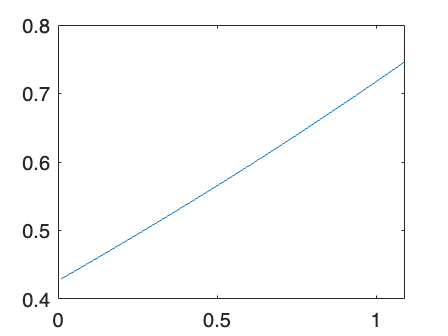



figure
plot(dl, HHNV);

% %plot(mu,DD)
% %legend('d-lim')

x = double(dl);
y = double(HHNV);
c = polyfit(x,y,1)

c =     0.2933    0.4215



cv = polyfit(x,y,2)

cv =     0.0275    0.2630    0.4270
